load('../2018/data/dc_corr'); addpath('functions'); load coastlines.mat
load('../2018/data/BelowRadarMPS.mat'); 

sf = struct();
sf.name = {'Fehmann', 'DeBilt', 'Ouadane', 'Trappes', 'Wideumont', 'Moggingen', 'Haidershogen', 'StGotthard', 'Planachaux'};
sf.date = [ NaT(1,2); [datetime(2007,8,18) datetime(2007,9,16)]; NaT(1,2); [datetime(2008,3,8) datetime(2008,5,7)]; [datetime(2007,9,18) datetime(2007,10,22)]; [datetime(2008,8,12) datetime(2008,11,6)];NaT(3,2) ];
sf.date2018 = sf.date;
for i=1:numel(sf.date)
    sf.date2018(i).Year = 2018;
end
sf.lat = [54.5000   52.1333   20.9333   48.5833   50.0333   47.7667   48.0833   46.5500   46.1667];
sf.lon = [11.2333    5.2833  -11.5833    1.5167    5.4333    9.0000   14.5167    8.5833    6.8333];

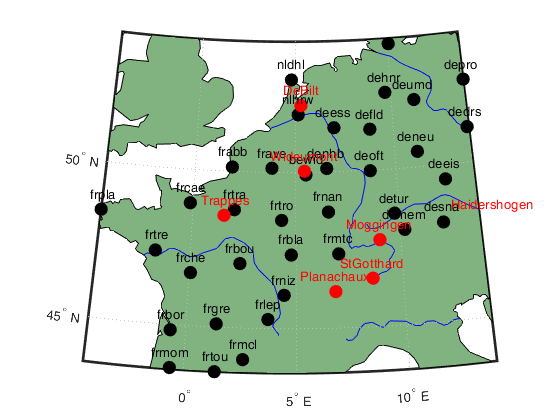

figure;
worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);
geoshow('landareas.shp', 'FaceColor', [0.5 0.7 0.5])
geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],100,'filled','k');
scatterm([sf.lat],[sf.lon],100,'filled','r');
textm([dc.lat]+.5,[dc.lon],{dc.name},'color','k','HorizontalAlignment','center');
textm(sf.lat+.5,sf.lon,sf.name,'Color','r','HorizontalAlignment','center');

%sf.match = {'','nlhrw','','frtra','bewid','demem','','',''};
sf.match = {'','nlhrw','','frtra','bewid','frmtc','','',''};
sf.file = {'','Bruderer2018-fig3-c.png','','Bruderer2018-fig3-d.png','Bruderer2018-fig3-e.png','Bruderer2018-fig4-d.jpg','','',''};

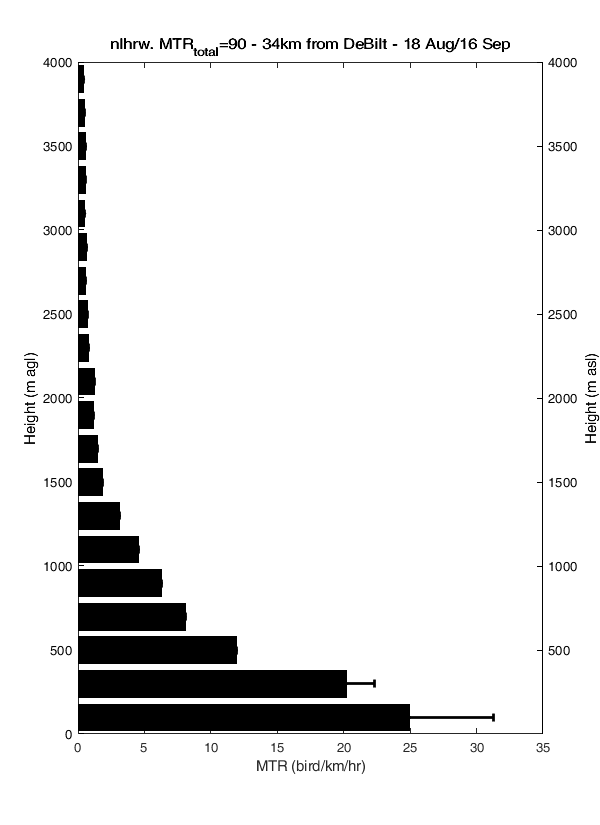

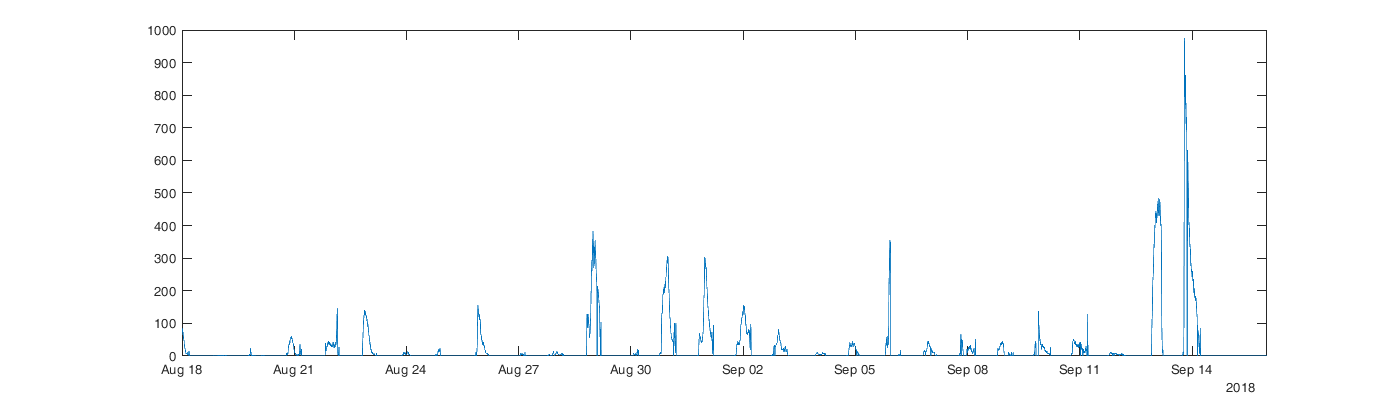

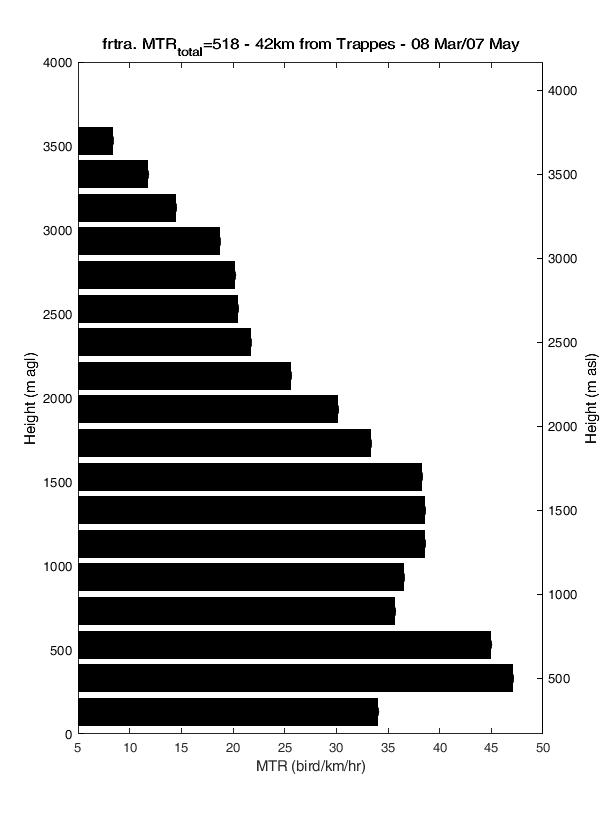

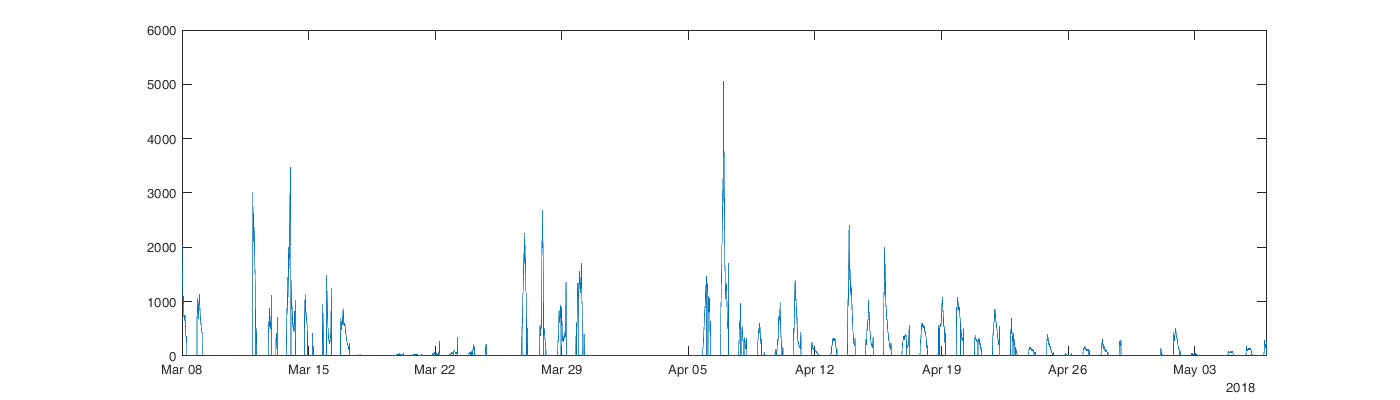

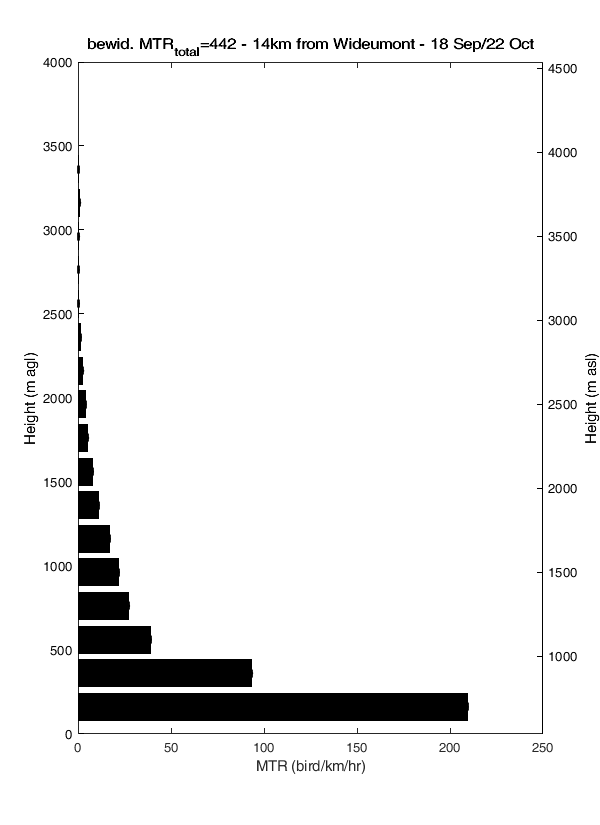

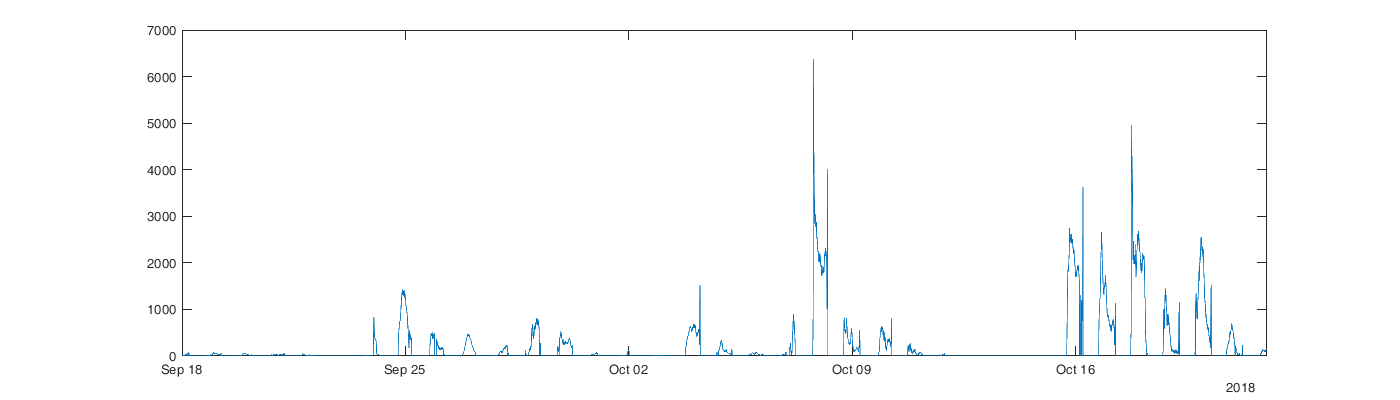

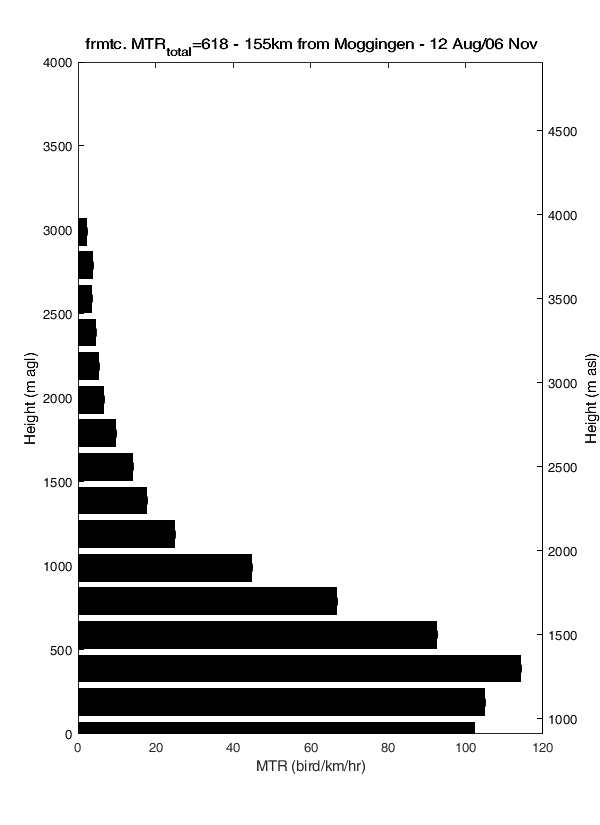

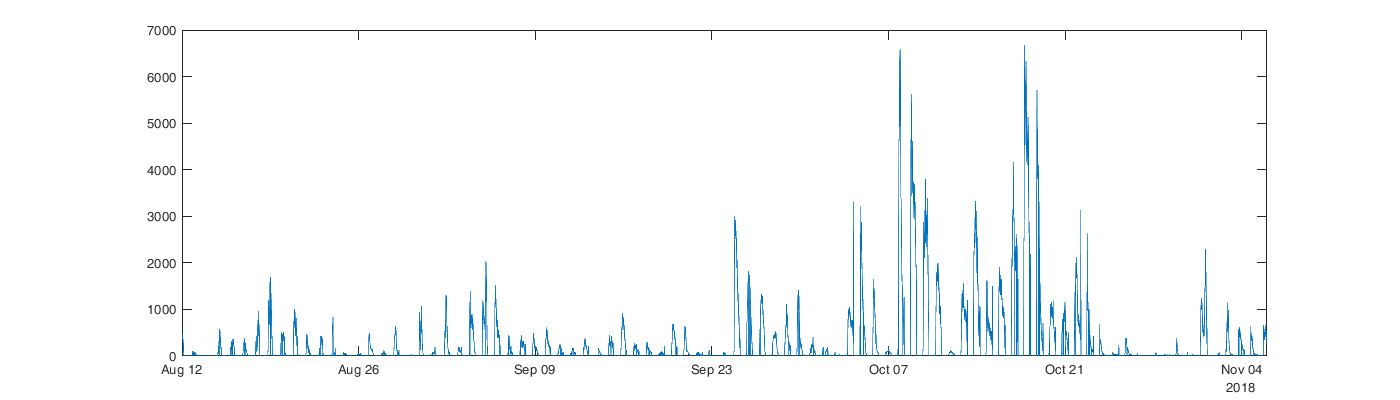

%figure('position',[0 0 800 1400]); u=1;
for i_sf = 1:numel(sf.match)
    if ~isempty(sf.match{i_sf})
        i_d = find(strcmp({dc.name},sf.match{i_sf}));
        id_t = dc(i_d).time>sf.date2018(i_sf,1) & dc(i_d).time<sf.date2018(i_sf,2);
                
        tmp = dc(i_d).dens4;
        MTR_alt = nan(size(tmp,2),size(MPS{i_d},3));
        for i_real=1:size(MPS{i_d},3)
            tmp(:,1:dc(i_d).scatter_lim-1) = MPS{i_d}(:,1:dc(i_d).scatter_lim-1,i_real);
            tmp2 = tmp .* sqrt( dc(i_d).u2.^2 + dc(i_d).v2.^2 );
            MTR_alt(:,i_real) = nanmean(tmp2(id_t,:));
        end
        
        MTR_alt = MTR_alt./1000*60*60*0.2; % bird/km^3 * m/s * 1/(m/km) * s/hr * km = bird/km/hr
        
        figure('position',[0 0 600 825]); hold on
        % ax=subplot(4,2,u); hold on; %box on;
        % barh(dc(i_d).alt-dc(i_d).heightDEM,mean(MTR_alt,2)./nansum(mean(MTR_alt,2))*100,'k');
        barh(dc(i_d).alt-dc(i_d).heightDEM,mean(MTR_alt,2),'k');
        % errorbar(mean(MTR_alt,2)./nansum(mean(MTR_alt,2))*100,dc(i_d).alt-dc(i_d).heightDEM,3*std(MTR_alt,[],2)./nansum(mean(MTR_alt,2))*100,'horizontal','.k','LineWidth',2)
        errorbar(mean(MTR_alt,2),dc(i_d).alt-dc(i_d).heightDEM,3*std(MTR_alt,[],2),'horizontal','.k','LineWidth',2);
        
        ylim([0 4000]);
        ylabel('Height (m agl)'); xlabel('MTR (bird/km/hr)');
        title( [dc(i_d).name '. MTR_{total}=' num2str(round(nansum(mean(MTR_alt,2)))) ' - ' num2str(round(lldistkm([dc(i_d).lat dc(i_d).lon], [sf.lat(i_sf) sf.lon(i_sf)]))) 'km from ' sf.name{i_sf} ' - ' datestr(sf.date2018(i_sf,1),'dd mmm') '/' datestr(sf.date2018(i_sf,2),'dd mmm')] )
        yyaxis right; a2=gca; a2.YAxis(2).Color = 'k';
        set(a2, 'YLim', [dc(i_d).heightDEM dc(i_d).heightDEM+4000]); ylabel('Height (m asl)')
        box on;
        
        % saveas(gcf,[dc(i_d).name '.png'])
%         subplot(4,2,u+1); 
%         img = imread(sf.file{i_sf});
%         imshow(img);
%         u=u+2;
        figure('position',[0 0 1400 400]);
        plot(dc(i_d).time(id_t), nansum(dc(i_d).dens4(id_t,:) .* sqrt( dc(i_d).u2(id_t,:).^2 + dc(i_d).v2(id_t,:).^2 )./1000*60*60*0.2,2))
        xlim(sf.date2018(i_sf,:))
    end
end

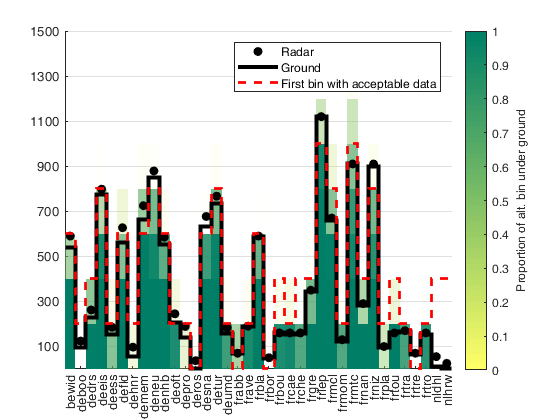

V=nan(25,37);
for i_d=1:numel(dc)
    V(:,i_d)=mean(dc(i_d).VolBelow)/.2;
end
V=1-V;
figure; hold on;
imagesc(1:37,dc(1).alt,V,'AlphaData',abs(V))
colormap(flipud(summer))%demcmap()
plot(1:37,[dc.height],'ok','MarkerFaceColor','k')
stairs(0.5:37.5,[dc.heightDEM dc(end).heightDEM],'-k','linewidth',3)
stairs(0.5:37.5,dc(1).alt([dc.scatter_lim dc(end).scatter_lim])-100,'--r','linewidth',2)
xticks(1:37)
xticklabels({dc.name})
yticks(dc(1).alt)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
xtickangle(90); axis tight
ylim([0 1500])
legend({'Radar','Ground','First bin with acceptable data'})
c=colorbar; c.Label.String='Proportion of alt. bin under ground';